## **Cocktail party decoding TRF example**

This is a follow-up of the BackwardTRF example. Please refer to that script for documentation and explanations on the backward TRF.

EEG signals were recorded as participants were presented with speech from two competing talkers using loudspeakers in an immersive setting, while also presented with background noise. Participants were asked to pay attention to one speech stream while ignoring the others. This script provides a step-by-step guide on the use of the backward TRF for decoding which speaker was attended to at a given moment.

Please refer to [https://cnspworkshop.net/resources.html](https://cnspworkshop.net/resources.html) for information on the authors and appropriate references, as well as for in-depth documentation.

'dataStim.mat' contains the stimulus features. 'pre_dataSub1.mat' contains the preprocessed EEG signals. Then, the script runs a typical forward TRF analysis to measure how strongly the EEG signals encode specific stimulus features, comparing the various datasets.

Note: Please see [https://cnspworkshop.net](https://cnspworkshop.net) and [https://diliberg.net](https://diliberg.net) for additional resources such as tutorials, videotutorials, and datasets.

Author: Giovanni M. Di Liberto ([https://diliberg.net](https://diliberg.net)) 

Please cite:

- mTRF-Toolbok: [https://www.frontiersin.org/articles/10.3389/fnhum.2016.00604/full](https://www.frontiersin.org/articles/10.3389/fnhum.2016.00604/full) 

- Open science framework: [https://nbdt.scholasticahq.com/article/124867-a-standardised-open-science-framework-for-sharing-and-re-analysing-neural-data-acquired-to-continuous-stimuli](https://nbdt.scholasticahq.com/article/124867-a-standardised-open-science-framework-for-sharing-and-re-analysing-neural-data-acquired-to-continuous-stimuli) 

Please check out

- mTRF-Toolbox - Considerations for applied research: [https://www.frontiersin.org/journals/neuroscience/articles/10.3389/fnins.2021.705621/full](https://www.frontiersin.org/journals/neuroscience/articles/10.3389/fnins.2021.705621/full) 

- Original study for the diliBach dataset: [https://elifesciences.org/articles/51784](https://elifesciences.org/articles/51784) 

- CND dataset available here: [https://cnspworkshop.net/resources.html](https://cnspworkshop.net/resources.html) 

### Workspace setup

This section clears the workspace and adds the library folders to the Matlab paths

clear
close all

addpath ./libs/cnsp_utils
addpath ./libs/cnsp_utils/cnd
addpath ../mtrf
addpath ./libs/fileDownload

### Data preparation

This section downloads the sample data. This sample dataset consists of 64-channel EEG time-series from one distinct individuals (the rest of the dataset is available here: [https://cnspworkshop.net/resources.html](https://cnspworkshop.net/resources.html)). The signals were filtered and downsampled to 100Hz (please see the documentation on this specific dataset for more details on the experiment and preprocessing). The dataStim.mat file contains features of the corresponding music stimulus (i.e., Hilbert envelope and note onsets).

Note that the following section (the data loader) is almost identical to the other example scripts. The kay difference is the name of the sample dataset 'datasetName'.

% Sample data from Carta et al., 2026 dataset
datasetName = "cocktailAttSwitch";

% Creating directory where the sample data will be downloaded
if ~exist(datasetName, 'dir')
    mkdir(datasetName)
end

% Setting up filenames and URL
stimFilename = "dataStim.mat";
eegFilenames = {'dataSub1.mat'};

dataStim_URL = "https://www.data.cnspworkshop.net/sampleData/"+datasetName+"/"+stimFilename;

% Download stimulus file
if ~isfile(datasetName+"/"+stimFilename)
    downloadFile(datasetName+"/"+"dataStim.mat", dataStim_URL, ShowFilename=true)
else
    disp('Skipping download. Stim file already present.')
end

Skipping download. Stim file already present.


% Download neural data file
for iiSub = 1:length(eegFilenames)
    dataSub_URL = "https://www.data.cnspworkshop.net/sampleData/"+datasetName+"/"+eegFilenames{iiSub};

    if ~isfile(datasetName+"/"+eegFilenames{iiSub})
        downloadFile(datasetName+"/"+eegFilenames{iiSub}, dataSub_URL, ShowFilename=true)
    else
        disp('Skipping download. EEG file already present.')
    end

end

Skipping download. EEG file already present.


nSubs = length(eegFilenames);

### Backward TRF model fit

Setting up mTRF hyperparameters

tmin = -200;
tmax = 600;
lambdas = 10.^(-6:2:6); % small set of lambdas (quick)
dirTRF = -1; % Backward TRF model
targetStimIdx = 1; % Index for the target speech envelope 
maskerStimIdx = 2; % Index for the masker speech envelope 

if tmin > tmax
    disp('Warning: tmin > tmax; setting tmax=tmin for the analysis')
    tmax = tmin;
end

Loading Stimulus and EEG data

subIdx = 1;

stimFilename = datasetName+"/"+"dataStim.mat";
load(stimFilename,'stim')
stim = cndNormalise(stim);

eegFilename = datasetName+"/pre_"+eegFilenames{subIdx}; 
load(eegFilename,'eeg')
eeg = cndNormalise(eeg); % Standardise neural data (preserving the ratio between channels)

Making sure that stim and neural data have the same length. The trial may end a few seconds after the end of the audio e.g., the neural data may include the break between trials. It would be best to do this chunking at preprocessing, but let's check here, just to be sure. The function returnes a version of stim and eeg where their lengths have been made equal by cutting the tail of the longer time-series where necessary.

% Downsampling stim if necessary
if eeg.fs < stim.fs
    stim = cndDownsample(stim, eeg.fs);
end

[stim,eeg] = cndCheckStimNeural(stim,eeg);

### Backward TRF

Determine optimal lambda

% Reducing the number of electrodes to make this example faster 
eeg.data = cellfun(@(x) x(:,1:8:end),eeg.data,'UniformOutput',false);

% Running cross validated attention decoding
% 'stats1' and 'stats2' contain the reconstruction correlations for the two
% streams. 'stats' contains the decoding accuracy and effect size for each
% lambda value.
[stats,stats1,stats2,t] = mTRFattncrossval(stim.data(targetStimIdx,:),stim.data(maskerStimIdx,:),eeg.data,eeg.fs,dirTRF,tmin,tmax,lambdas,'verbose',0);

% Calculating optimal lambda. Display and store results
[maxR1,bestLambda1] = max(squeeze(mean(stats1.r,1))); % mean across trials
[maxR2,bestLambda2] = max(squeeze(mean(stats2.r,1))); % mean across trials

disp(['r_target = ',num2str(round(maxR1,4))])

r_target = 0.0461


disp(['r_masker = ',num2str(round(maxR2,4))])

r_masker = 0.0223


disp("Attention decoding accuracy = "+round(max(stats.acc)*100,1)+"%")

Attention decoding accuracy = 85%


'stats.r' contains the envelope reconstruction correlations for all the trials and lambdas (20x5, in this case).

Let's have a look at the tuning curve:

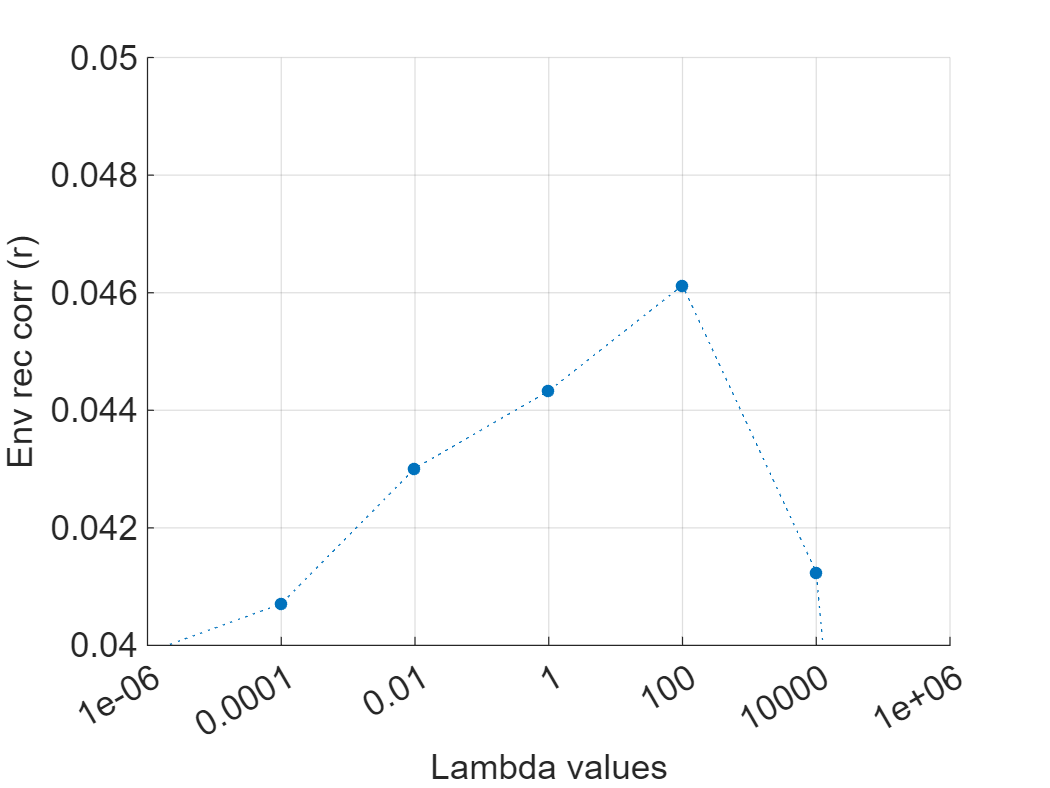

figure;
plot(mean(stats1.r,1),'.:','MarkerSize',15)
xticks(1:length(lambdas))
xticklabels(lambdas)
xlim([1,length(lambdas)])
ylim([0.04,0.05])
xlabel('Lambda values')
ylabel('Env rec corr (r)')
run prepExport.m % beautify the plot
grid on

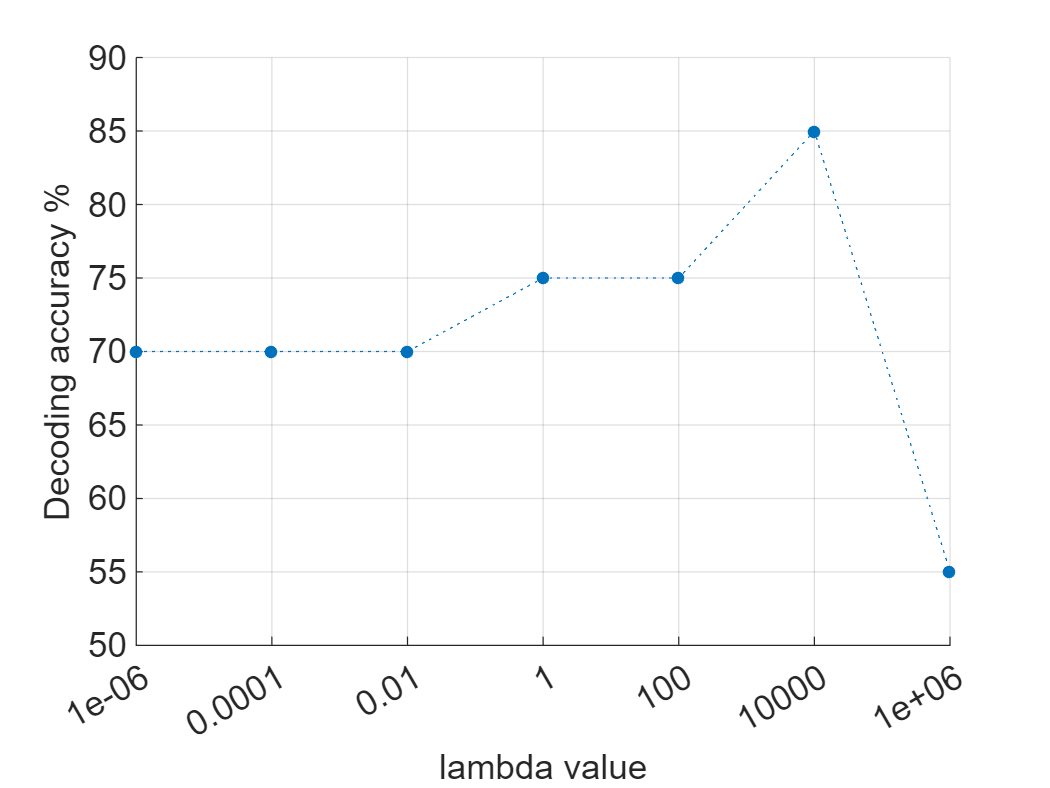


figure;
plot(stats.acc*100,'.:','MarkerSize',15)
xlabel('lambda value')
xticks(1:length(lambdas))
xticklabels(lambdas)
xlim([1,length(lambdas)])
ylim([50,90])
ylabel('Decoding accuracy %')
run prepExport.m % beautify the plot
grid on

Let's have a look at the correlation values across trials (segments of EEG data) for the optimal lambda:

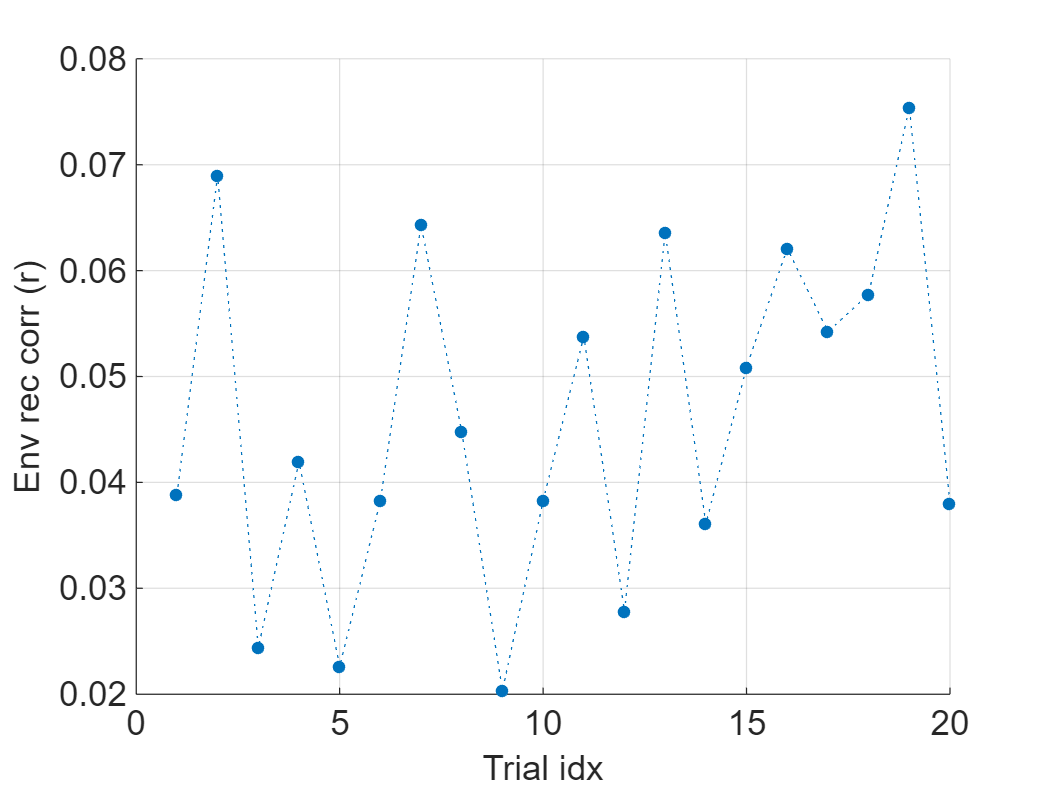

figure;
plot(stats1.r(:,bestLambda1),'.:','MarkerSize',15)
xlabel('Trial idx')
ylabel('Env rec corr (r)')
xlim([0,20])
run prepExport.m % beautify the plot
grid on

Plotting the target envelope, the masker envelope, and the reconstructed target envelope together (for the last trial only)

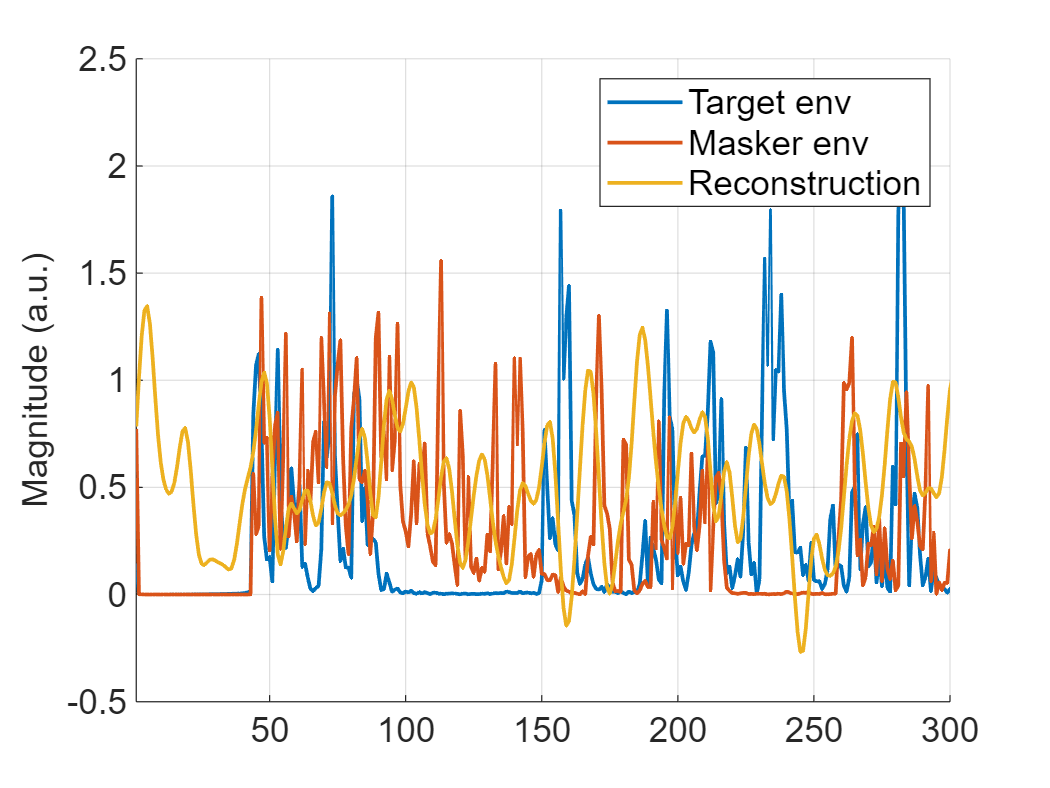

% [stats,stats1,stats2,t] = mTRFtrain(,stim.data(maskerStimIdx,:),,eeg.fs,dirTRF,tmin,tmax,lambdas,'verbose',0);
attentionModel = mTRFtrain(stim.data(targetStimIdx,1:end-1),eeg.data(:,1:end-1),eeg.fs,dirTRF,tmin,tmax,lambdas(bestLambda1),'verbose',0);

[pred,stats] = mTRFpredict(stim.data(targetStimIdx,end),eeg.data(:,end),attentionModel,'verbose',0);

pred = pred-prctile(pred,5);
envT = stim.data{targetStimIdx,end};
envM = stim.data{maskerStimIdx,end};

figure;
plot(envT/prctile(envT,95),'LineWidth',1.5)
hold on
plot(envM/prctile(envM,95),'LineWidth',1.5)
plot(pred/prctile(pred,95),'LineWidth',1.5)
legend({'Target env','Masker env','Reconstruction'})
ylabel("Magnitude (a.u.)")
xlim([1,300])
grid on
run prepExport.m

Given the high level of noise at the single subject level, it is difficult to assess visually the quality of the result. Nonetheless, the correlation and classification metrics offer quantitative evidence on the sensitivity of EEG to auditory selective attention. This result has intrigued numerous scientists, leading to an entire line of work across academia and industry. Indeed, this basic TRF decoding should be taken as a baseline model, which can be improved with more data, data with higher SNR (e.g., intracranial EEG), and more elaborate models.